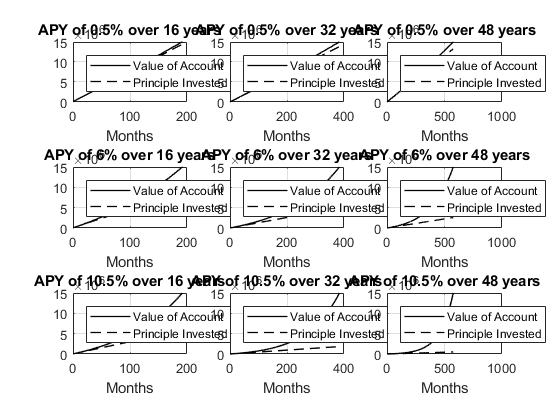

% Part 1
i = [0.005, 0.06, 0.105];
D = [16, 32, 48];

C = zeros(3,3);
P = zeros(3,3);
y = zeros(3,3);
fn_y = @(n,i,C,D) (12 * C / i) .* (1 + i/12).^(n+1);

for j = 1:1:3
    for k = 1:1:3
        % Figure out monthly payments
        C(j,k) = i(j) * 15E6 / (12*(1+i(j)/12)*((1+i(j)/12)^(12*D(k))-1));
        
        % Check that these payments make sense recursively
        y_t = zeros(12*D(k)+1,1);
        for l = 0:1:(12*D(k)-1)
            y(j,k) = (1+i(j)/12) * y(j,k) + C(j,k);
            y_t(l+1) = y(j,k);
        end
        y(j,k) = (1+i(j)/12) * y(j,k);
        y_t(12*D(k)+1) = y(j,k);
        
        % Calculate principle
        P(j,k) = 12*D(k)*C(j,k);
        
        % Plot the value of the retirement account as a function of month over the investment interval.
        n = 0:1:(D(k)*12);
        %y_t = fn_y(n, i(j), C(j,k), D(k));
        P_t = (n+1) .* C(j,k);
        subplot(3,3,((j-1)*3+k-1)+1);
        plot(n, y_t, '-', n, P_t, '--', 'color', [0,0,0], 'linewidth', 1);
        ylim([0 1.5E7]);
        xlabel('Months');
        %ylabel("Value of Account");
        title("APY of " + string(i(j)*100)+"% over " + string(D(k)) + " years");
        grid on;
        legend('Value of Account', 'Principle Invested', 'Location','northwest');
    end
end

C

C =    1.0e+04 *

    7.5027    3.6014    2.3037
    4.6483    1.2892    0.4472
    3.0073    0.4754    0.0867


C_s = strings(3);
for i=1:3
    for j=1:3
        C_s(i,j) = "$" + num2bank(C(i,j));
    end
end
C_s

C_s = 3×3 string array
    "$75,026.66"    "$36,013.91"    "$23,037.34"
    "$46,483.26"    "$12,892.47"    "$4,472.18" 
    "$30,073.22"    "$4,753.53"     "$866.71"   


y

y =    1.0e+07 *

    1.5000    1.5000    1.5000
    1.5000    1.5000    1.5000
    1.5000    1.5000    1.5000


P

P =    1.0e+07 *

    1.4405    1.3829    1.3270
    0.8925    0.4951    0.2576
    0.5774    0.1825    0.0499


P_s = strings(3);
for i=1:3
    for j=1:3
        P_s(i,j) = "$" + num2bank(P(i,j));
    end
end
P_s

P_s = 3×3 string array
    "$14,405,120.13"    "$13,829,342.25"    "$13,269,511.84"
    "$8,924,786.54"     "$4,950,710.73"     "$2,575,978.17" 
    "$5,774,059.16"     "$1,825,359.28"     "$499,227.07"   
